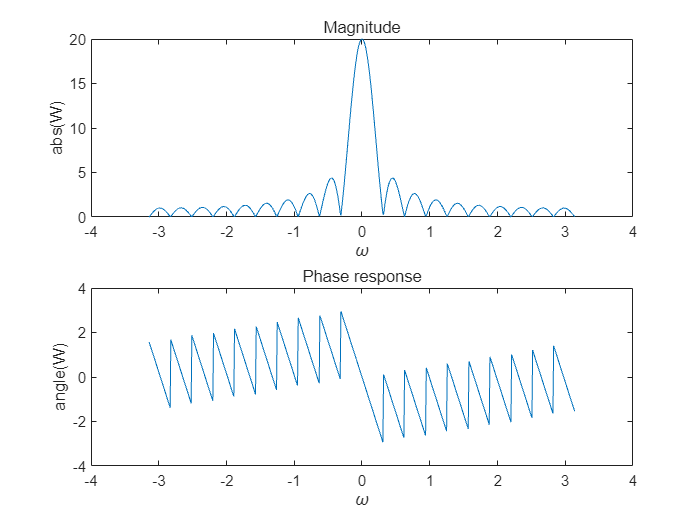


clc,
clear
close all

N=20;
w=-pi:0.01:pi;
% excepting for w equals 0
W = (w==0).*N+(w~=0).*exp(-1i*w*(N-1)/2).*sin(w*N/2)./(sin(w/2));

hold on;
subplot(2,1,1);
plot(w,abs(W));
xlabel('\omega'),ylabel('abs(W)'),title('Magnitude');
subplot(2,1,2);
plot(w,angle(W));
xlabel('\omega'),ylabel('angle(W)'),title('Phase response');

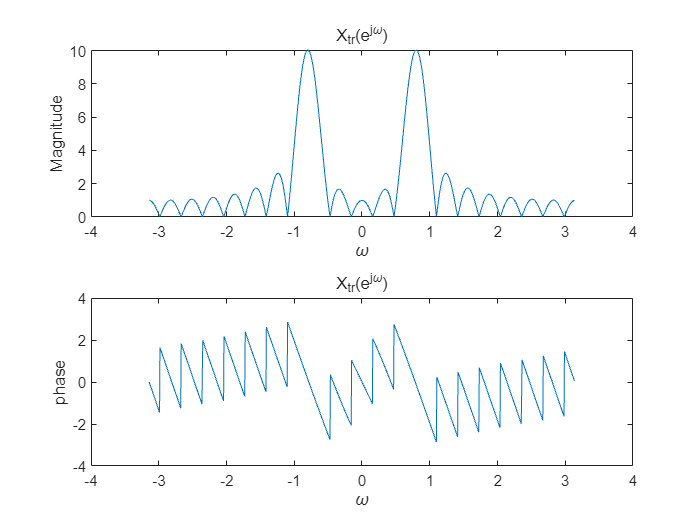

clear;close all;clc;
n=0:19;
x=cos(pi*0.25*n);
[X,w]=DTFT(x,1024);
subplot(2,1,1)
plot(w,abs(X));
xlabel('\omega'),ylabel('Magnitude'),title('X_{tr}(e^{j\omega})');
subplot(2,1,2)
plot(w,angle(X));
xlabel('\omega'),ylabel('phase'),title('X_{tr}(e^{j\omega})')